# 4.5 FFT 的应用：快速卷积（补零、重叠相加）与快速相关（找时延）

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end
rng(20260918);

## 演示1：快速卷积——补零到 N ≥ N1+N2−1 且 N=2^v，FFT 相乘再 IFFT（教材 4.5.1）

N1 = 1000; N2 = 101;
x = randn(1, N1);
h = sinc_lowpass(N2, 0.1);                         % 101 点低通（第 7 章内容，这里只当一个 h 用）
yDirect = conv(x, h);
Nfft = 2^nextpow2(N1 + N2 - 1);                    % 2048 ≥ 1100
yFast = real(ifft(fft(x, Nfft) .* fft(h, Nfft)));
yFast = yFast(1:N1+N2-1);
errFast = max(abs(yFast - yDirect));

## 演示2：两个长序列卷积的用时——conv 与 FFT 法

Nlist = 2.^(10:14); tConv = zeros(size(Nlist)); tFFT = zeros(size(Nlist));
for i = 1:numel(Nlist)
    L = Nlist(i); a = randn(1, L); b = randn(1, L); Nf = 2^nextpow2(2*L - 1);
    fftconv = @() real(ifft(fft(a, Nf) .* fft(b, Nf)));
    c1 = conv(a, b); c2 = fftconv(); c2 = c2(1:2*L-1);            % 各先跑一次热身（fft 首次调用要建计划）
    tc = zeros(1, 5); tf = zeros(1, 5);
    for r = 1:5, t0 = tic; c1 = conv(a, b); tc(r) = toc(t0); t0 = tic; c2 = fftconv(); tf(r) = toc(t0); end
    tConv(i) = min(tc); tFFT(i) = min(tf); c2 = c2(1:2*L-1);   % 取 5 次中的最小值
    assert(max(abs(c1 - c2)) < 1e-6*L, 'FFT 卷积与 conv 不一致');
end

## 演示3：很长的信号与短的 h——重叠相加法（教材 4.5.1 第 1 条的第二种情形）

Nlong = 20000; xLong = randn(1, Nlong); B = 1024;  % 每段 1024 点，每段结果长 1024+101−1
yOA = zeros(1, Nlong + N2 - 1); NfB = 2^nextpow2(B + N2 - 1);
H = fft(h, NfB);
for start = 1:B:Nlong
    seg = xLong(start:min(start+B-1, Nlong));
    yseg = real(ifft(fft(seg, NfB) .* H)); yseg = yseg(1:numel(seg)+N2-1);
    yOA(start:start+numel(yseg)-1) = yOA(start:start+numel(yseg)-1) + yseg;   % 重叠部分相加
end
errOA = max(abs(yOA - conv(xLong, h)));

## 演示4：快速相关——找回声的时延（教材 4.5.2）

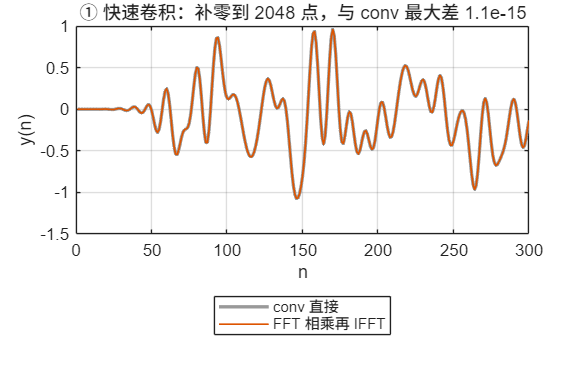

Ns = 4096; s = randn(1, Ns); delay = 37;
r = 0.6*[zeros(1, delay), s(1:end-delay)] + 0.5*randn(1, Ns);   % 回声：延迟 37、衰减 0.6，加噪声
Nc = 2^nextpow2(2*Ns - 1);
rxy = real(ifft(fft(r, Nc) .* conj(fft(s, Nc))));  % 互相关：R(k) = X(k)·S*(k)
rxy = rxy(1:Ns);                                   % 只看正时延
[~, idx] = max(rxy); delayFound = idx - 1;

if ~LIVE, f1 = figure('Name','04 快速卷积与相关','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); plot(yDirect(1:300), 'Color', [0.6 0.6 0.6], 'LineWidth', 2); hold on; plot(yFast(1:300), 'LineWidth', 1);
grid on; title(sprintf('① 快速卷积：补零到 %d 点，与 conv 最大差 %.1e', Nfft, errFast)); xlabel('n'); ylabel('y(n)');
legend('conv 直接','FFT 相乘再 IFFT');

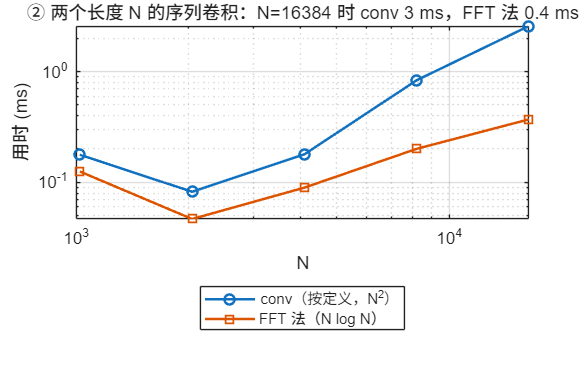

newpanel(); loglog(Nlist, tConv*1e3, '-o', 'LineWidth', 1.5); hold on; loglog(Nlist, tFFT*1e3, '-s', 'LineWidth', 1.5); grid on;
title(sprintf('② 两个长度 N 的序列卷积：N=%d 时 conv %.0f ms，FFT 法 %.1f ms', Nlist(end), tConv(end)*1e3, tFFT(end)*1e3));
xlabel('N'); ylabel('用时 (ms)'); legend('conv（按定义，N^2）','FFT 法（N log N）');

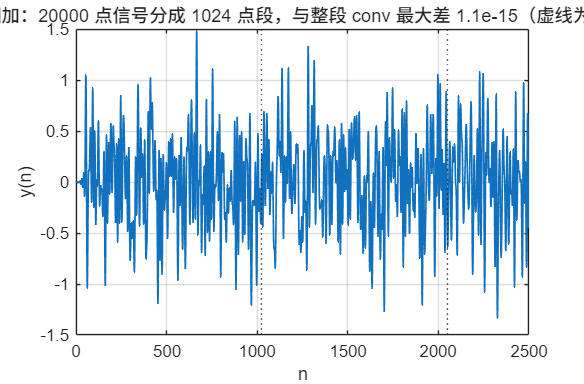

newpanel(); plot(yOA(1:2500), 'LineWidth', 1); hold on; xline(B:B:2500, ':'); grid on;
title(sprintf('③ 重叠相加：20000 点信号分成 1024 点段，与整段 conv 最大差 %.1e（虚线为分段边界）', errOA)); xlabel('n'); ylabel('y(n)');

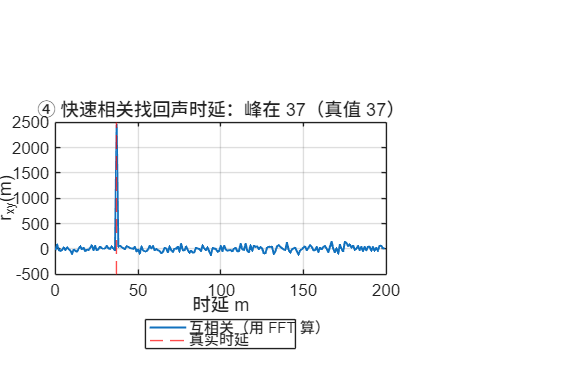

newpanel(); plot(0:199, rxy(1:200), 'LineWidth', 1.2); hold on; xline(delay, 'r--'); grid on;
title(sprintf('④ 快速相关找回声时延：峰在 %d（真值 %d）', delayFound, delay)); xlabel('时延 m'); ylabel('r_{xy}(m)');
legend('互相关（用 FFT 算）','真实时延');

if ~LIVE, sgtitle('FFT 的两个用处：把卷积和相关都变成“变换—相乘—反变换”'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '04-fast-convolution.png'), 'Resolution', 150); end

## 教师核验

assert(errFast < 1e-10, '快速卷积不符');
assert(errOA < 1e-9, '重叠相加不符');
assert(delayFound == delay, '相关峰位置不符');
assert(tFFT(end) < tConv(end), '大 N 时 FFT 法应更快');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'N1', N1, 'N2', N2, 'Nfft', Nfft, 'fast_conv_err', errFast, ...
    'timing_N', Nlist, 'conv_seconds', tConv, 'fftconv_seconds', tFFT, ...
    'overlap_add_block', B, 'overlap_add_err', errOA, 'echo_delay_true', delay, 'echo_delay_found', delayFound, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-fast-conv.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

       matlab_version: '25.2.0.3360999 (R2025b) Update 7'
               run_at: '2026-09-18 19:56:04'
                   N1: 1000
                   N2: 101
                 Nfft: 2048
        fast_conv_err: 1.1102e-15
             timing_N: [1024 2048 4096 8192 16384]
         conv_seconds: [1.7720e-04 8.2100e-05 1.7900e-04 8.3560e-04 0.0026]
      fftconv_seconds: [1.2510e-04 4.6600e-05 8.9500e-05 2.0060e-04 3.7040e-04]
    overlap_add_block: 1024
      overlap_add_err: 1.1102e-15
      echo_delay_true: 37
     echo_delay_found: 37
    all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results



function h = sinc_lowpass(L, fcNorm)
% 窗函数法低通（Hann 窗），fcNorm 为相对 fs 的截止频率；仅作演示用的 h
k = 0:L-1; z = 2*pi*fcNorm*(k - (L-1)/2);
hd = 2*fcNorm*((z == 0) + (z ~= 0).*sin(z + (z == 0))./(z + (z == 0)));
h = hd .* (0.5 - 0.5*cos(2*pi*k/(L-1))); h = h/sum(h);
end

function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end